## **OBECNÝ CYKLUS SPALOVACÍCH MOTORŮ**

 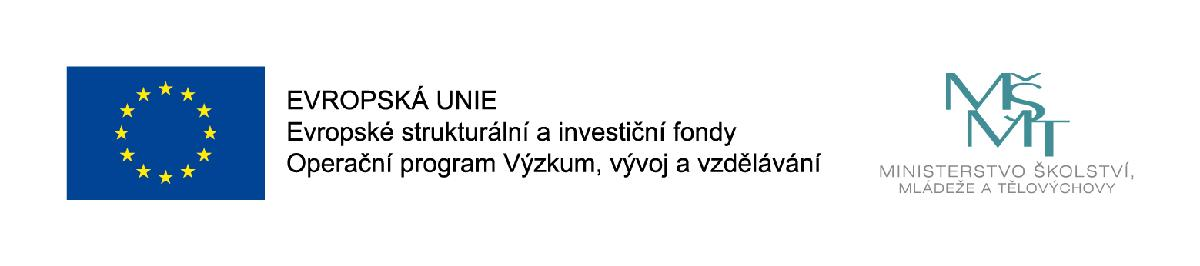

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

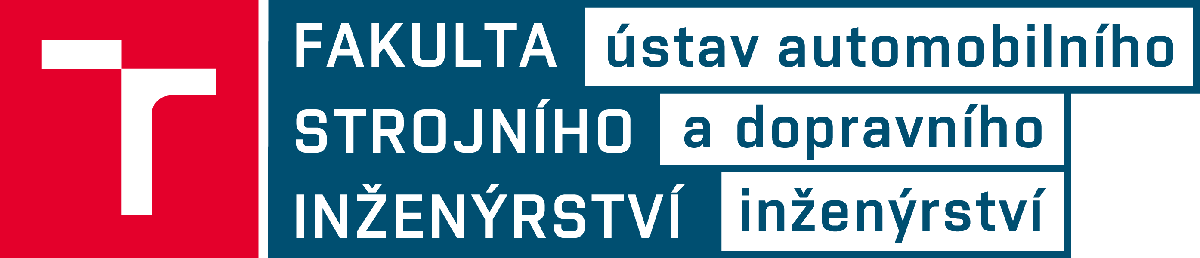

Obecný teoretický cyklus spalovacího motoru má jak smíšený přívod tepla, tak i smíšený odvod tepla. Tento cyklus lze uvažovat např. tehdy, jsou-li na počátku pohybu pístu z dolní úvrati ještě částečně otevřeny sací ventily, nebo též u přeplňovaných spalovacích motorů s turbínou poháněnou výfukovými plyny aj.

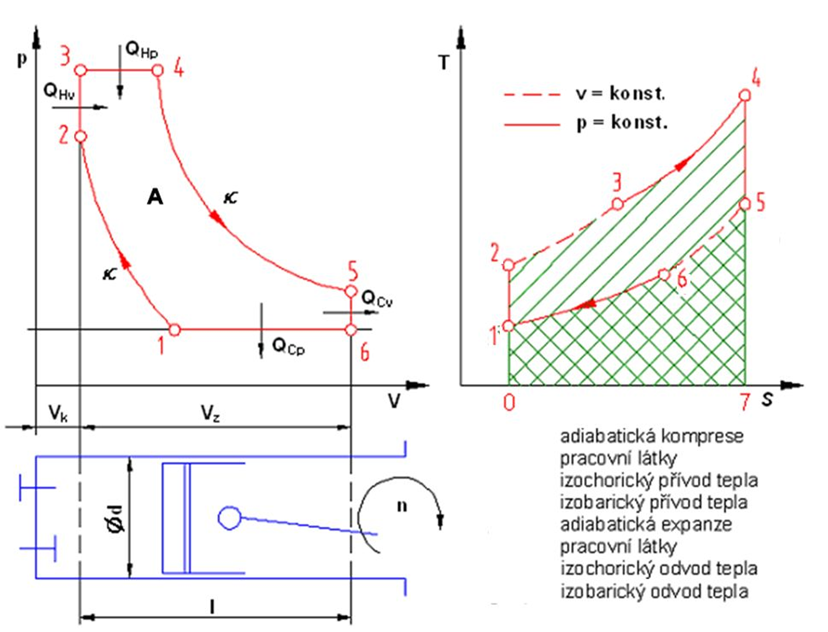

Zdvihový objem              $V_Z=V_1-V_2$  

Kompresní objem          $V_K=V_2$

Kompresní poměr          $${\epsilon} = \frac{V_1}{V_2}$$

Stupeň plnění                $${\phi} = \frac{V_4}{V_3}$$

Stupeň zvýšení tlaku      $${\psi} = \frac{p_3}{p_2}$$

Expanzní  poměr             $${\beta} = \frac{V_5}{V_4}$$


$$${\eta _t} = 1 - \frac{{\phi \frac{\beta }{\varepsilon }\left[ {\Psi {{\left( {\frac{\varepsilon }{\beta }} \right)}^\kappa } + \kappa  - 1} \right] - \kappa }}{{{\varepsilon ^{\kappa  - 1}}[\kappa  \cdot \Psi {\kern 1pt} (\phi  - 1) + \Psi  - 1{\kern 1pt} ]}}$$$


# 
$$${\eta _t} = f\left( {\kappa ,\;\varepsilon ,\;\phi ,\;\Psi ,\;\beta } \right)$$$


### **ATKINSONŮV CYKLUS**

Atkinsonův (superexpanzní)poměr 


$$\[\gamma  = \frac{\beta }{\varepsilon }\]$$


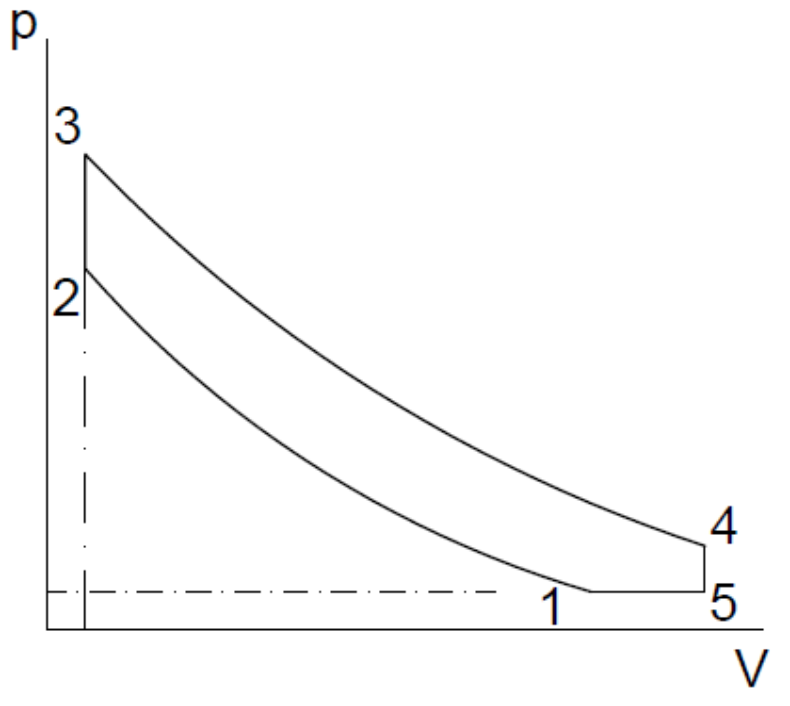

**MILLERŮV CYKLUS**

Millerův poměr  $\[\gamma  = \frac{\beta }{\varepsilon }\]$

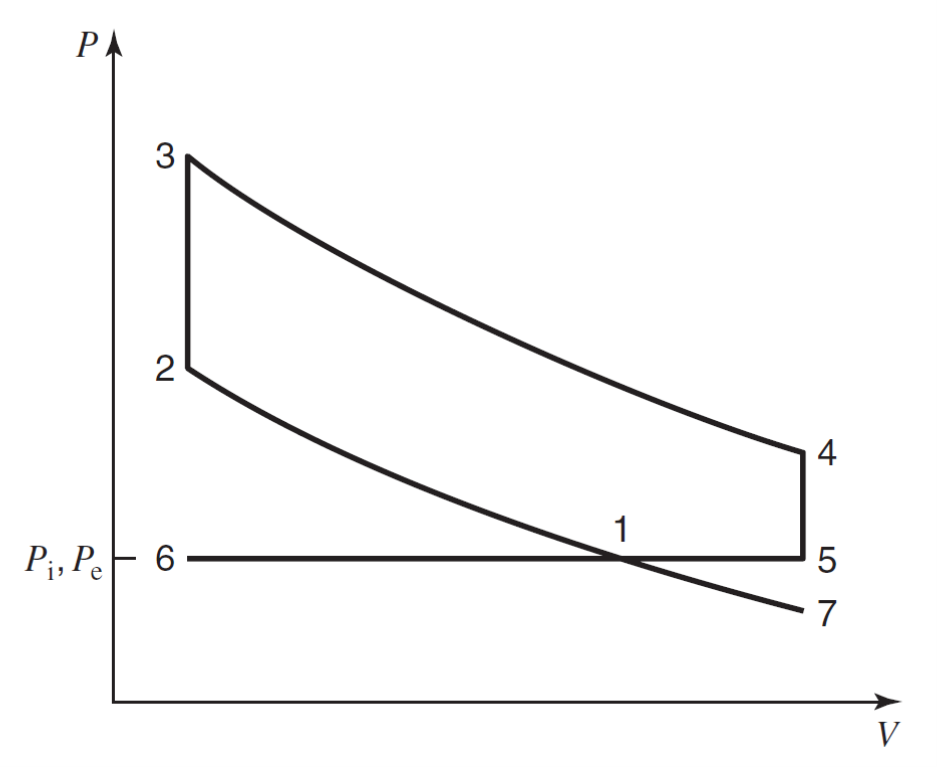

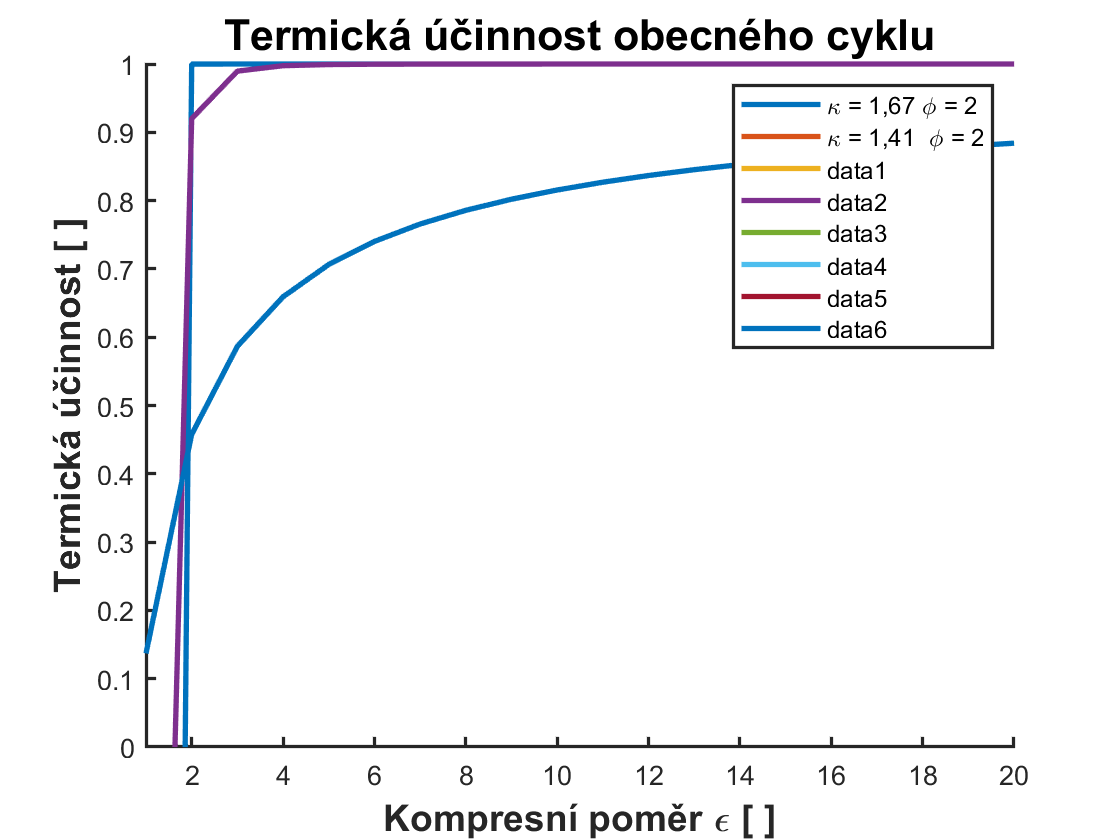

clear;
subplot(1,1,1);
i = 1;
phi = 2;
psi = 1.5;
eps_v = zeros(1, 19);
eta_t_12 = zeros(1, 19);
eta_t_22 = zeros(1, 19);
eta_t_32 = zeros(1, 19);
eta_t_13 = zeros(1, 19);
eta_t_23 = zeros(1, 19);
eta_t_33 = zeros(1, 19);
for eps=1:1:20
    eps_v(i) = eps;
    beta = eps_v(i)*1.2;
    a = (phi*beta/eps_v(i)*(psi*(eps_v(i)/beta)^kappaB(1)+kappaB(1)-1)-kappaB(1));
    b = (eps_v(i)^(kappaB(1)-1)*(kappaB(1)*psi*(phi-1)+psi-1));
    eta_t_12(i) = 1 - a/b;   
    i = i + 1;
end
title('Termická účinnost obecného cyklu','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Kompresní poměr \epsilon [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Termická účinnost [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([1 20]);
ylim([0 1]);
set(gca, 'linewidth',1.2);
hold on;
plot(eps_v,eta_t_12,'-','linewidth',2);
hold off;
grid on;
%legend('\kappa = 1,67 \phi = 2','\kappa = 1,41  \phi = 2','\kappa = 1,3 \phi = 2','\kappa = 1,67 \phi = 3','\kappa = 1,41  \phi = 3','\kappa = 1,3 \phi = 3')

Poissonova konstanta

function [result] = kappaB(atom)
              switch atom
                  case 1  
                    result = 1.67;
                  case 2
                    result = 1.41;
                  case 3  
                    result = 1.3;  
                  otherwise
                    result = 1.3;  
              end     
end

Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end